# Applied Mathematics

## Numerical Linear Algebra

### Dense vs. Sparse Matrices 

Create the following matrix (1000 rows/columns):

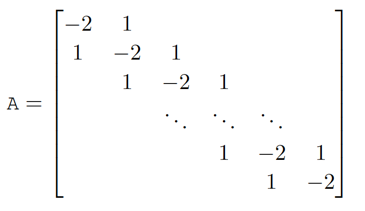

n = 1000;

Ad = diag(-2*ones(n,1),0) + diag(ones(n-1,1),-1) + ...
     diag(ones(n-1,1),1);
s1 = whos('Ad');
disp(s1.bytes)

This is a **sparse matrix**, a matrix with relatively small number of nonzero entries, compared to its size.

Let $A\in R^{m\times n}$ be a sparse matrix with $n_z$ nonzeros. Dense storage requires $\mathrm{mn}$ entries.

**Sparse matrix storage formats**

Triplet format

- Store nonzero values and corresponding row/column

- Storage required = ${3n}_z$ ($2n_z$ `int`s and $n_z$ `double`s)

- Simplest but most inefficient storage format

- General in that no assumptions are made about sparsity structure

- Used by MATLAB (column-wise)

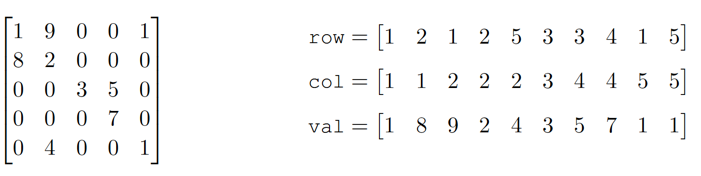

Compressed Sparse Row (CSR) format

- Store nonzero values, corresponding column, and pointer into value array corresponding to first nonzero in each row

- Storage required = $2n_z +m$

Compressed Sparse Column (CSC) format

- Store nonzero values, corresponding row, and pointer into value array corresponding to first nonzero in each column

- Storage required = $2n_z +n$

Diagonal Storage format

- Useful for banded matrices

Skyline Storage format

Block Compressed Sparse Row (BSR) format

#### Break-even point for sparse storage

For $A\in R^{m\times n}$  with $n_z$ nonzeros, there is a value of $n_z$ where sparse vs dense storage is more efficient.

- For the triplet format, the cross-over point is defined by ${3n}_z =\mathrm{mn}$, so if $n_z \le \frac{\mathrm{mn}}{3}$ use sparse storage, otherwise use dense format.

- Cross-over point depends not only on $m$, $n$, $n_z$ but also on the data types of `row, col, val.`

Besides storage efficiency, data access for linear algebra applications and ability to exploit symmetry in storage is also important.

**Quiz.**

Suppose you have a tridiagonal 1000x1000 matrix. All entries in those three diagonals are non-zero. Calculate how many numbers can we omit if we store it as a triplet instead of a full matrix?

""

It sounds that a tridiagonal matrix is better stored as a triplet. For a tridiagonal `nxn` matrix, find the greatest `n` in which the triplet is not helpful in saving memory for a tridiagonal matrix where all entries in those diagonals are non-zero.

""

#### Create Sparse Matrices

- Allocate space for $m\times n$ sparse matrix with $n_z$ nonzeros: `S = spalloc(m; n; nz)`

- Convert full matrix A to sparse matrix S: `S = sparse(A)`

- Create $m\times n$ sparse matrix with spare for $n_z$ nonzeros from triplet `(row,col,val)`: `S = sparse(row,col,val,m,n,nz)`

- Create matrix of 1s with sparsity structure defined by sparse matrix S: `R = spones(S)`

- Sparse identity matrix of size $m\times n$: `I = speye(m,n)`

- Create sparse uniformly distributed random matrix from sparsity structure of sparse matrix S: `R = sprand(S)`

- Create sparse uniformly distributed random matrix of size $m\times n$ with approximately $\mathrm{mn}\rho \;$ nonzeros and condition number roughly $\kappa \;$ (sum of rank 1 matrices): `R = sprand(m,n,rho,1/kappa)`

- Create sparse normally distributed random matrix: `R = sprandn(S), R = sprandn(m,n,rho,1/kappa)`

- Create sparse symmetric uniformly distributed random matrix: `R = sprandsym(S), R = sprandsym(n,rho,1/kappa)`

- Import from sparse matrix external format: `spconvert`

- Create sparse matrices from diagonals: `spdiags `(Can also extract nonzero diagonals from matrix, Extract diagonals of A specified by d, Replaces the diagonals of A specified by d with the columns of B, Create an $m\times n$ sparse matrix from the columns of B and place them along the diagonals specified by d)

**Demo.** Create the same matrix as above using `spdiags`

n = 1000;
As = spdiags([ones(n,1),-2*ones(n,1),ones(n,1)],-1:1,n,n);
s2 = whos('As');
s2.bytes

s1.bytes/s2.bytes

isequal(As, sparse(Ad))

#### Sparse storage information

- Determine if matrix is stored in sparse format: `issparse(S)`

- Number of nonzero matrix elements: `nz = nnz(S)`

- Amount of nonzeros allocated for nonzero matrix elements: `nzmax(S)`

- Extract nonzero matrix elements: If `(row, col, val)` is sparse triplet of S, `val = nonzeros(S), [row,col,val] = find(S)`

#### Sparse and dense matrix functions

- Convert sparse matrix to dense matrix: `A = full(S)`

- Apply function (described by function handle func) to nonzero elements of sparse matrix: `F = spfun(func, S)` 

func = @exp;
spfun(func,speye(3))
func(speye(3))

- Plot sparsity structure of matrix: `spy(S)`

spy(As)

#### Reordering Functions

- `amd` Approximate minimum degree permutation

- `colamd` Column approximate minimum degree permutation

- `colperm` Sparse column permutation based on nonzero count

- `dmperm` Dulmage-Mendelsohn permutation/decomposition

- `randperm` Random permutation

- `symamd` Symmetric approximate minimum degreepermutation

- `symrcm` Sparse reverse Cuthill-McKee ordering

#### Sparse Matrix Tips

Don't change sparsity structure (pre-allocate)

- Do not want to dynamically grows triplet

- Each component of triplet must be stored contiguously

Accessing values (may be) slow in sparse storage as location of row/columns is not predictable

- If `S(i,j)` is requested, must search through row, col to find i, j

Component-wise indexing to assign values is expensive

- Requires accessing into an array

- If `S(i,j)` is previously zero, then `S(i,j)= c` changes sparsity structure

### Matrix Decompositions and Direct Solvers

#### Rank

[rank(rand(100,34)), rank(rand(100,1)*rand(1,34))]

#### Norms

a = rand(3,4);
norm(a,2) % 2-norm, default
norm(a,1) % 1-norm
norm(a,Inf) % infinity norm
norm(a,'fro') % Frobenius norm

Estimate matrix 2-norm for sparse matrices or large, full matrices

norm(Ad)
normest(As,1e-4)

#### Solve linear system $\mathrm{Ax}=b$ by factorizing A.

- If A can be decomposed as $A=\mathrm{BC}$, then the problem can be reduced to solving $\mathrm{By}=b$ and $\mathrm{Cx}=y$ where B and C are matrices such that these two systems are easy to solve.

- Examples of easy-to-solve matrices: diagonal, triangular, orthogonal

- For overdetermined system of equations, solve the linear least squares problem $\mathrm{min}\;\frac{1}{2}||\mathrm{Ax}-b||_2^2$

**Note: **

Use backslash to solve Ax = b with a direct method, i.e.,` u`se` x = A\b `rather than` x = inv(A)* b`

#### LU Decomposition

$A=\mathrm{LU}$ where A is non-singular, L is lower-triangular, and U is upper triangular.

**Pivoting**

Gaussian elimination is unstable without pivoting:

- Partial pivoting: $\mathrm{PA}=\mathrm{LU}$

- Complete pivoting: $\mathrm{PAQ}=\mathrm{LU}$

**LU factorization, partial pivoting applied to L**

`[L,U] = lu(A)`

- $A=\left(P^{-1} \tilde{L} \right)U=\mathrm{LU}$ where $\mathrm{U}$ upper tri, $\tilde{L}$ lower tri, $P$ row permutation

`Y = lu(A)`

- If A in sparse format, strict lower triangular of Y contains L and upper triangular contains U

- Permutation information lost

**LU factorization, partial pivoting P explicit**

`[L,U,P] = lu(A)`

- 
$$\mathrm{PA}=\mathrm{LU}$$


`[L,U,p] = lu(A,'vector')`

- 
$$A\left(p;:\right)=\mathrm{LU}$$


**LU factorization, complete pivoting P,Q explicit**

`[L,U,P,Q] = lu(A)`

- 
$$\mathrm{PAQ}=\mathrm{LU}$$


`[L,U,p,q] = lu(A,'vector')`

- 
$$A\left(p;q\right)=\mathrm{LU}$$


Additional `lu` call syntaxes that give

- Control over pivoting thresholds

- Scaling options

- Calls to UMFPACK vs LAPACK

#### Demo

load demo/matrix_lu.mat
A = sparse(linsys.row,linsys.col,linsys.val);
b = linsys.b;
clear linsys;

Compute LU decomposition and generate a spy plot of L and U

[L,U] = lu(A);
figure;
subplot(1,3,1); spy(A); title('A');
subplot(1,3,2); spy(L); title('L');
subplot(1,3,3); spy(U); title('U');
norm(A - L*U,'fro')

Compute LU decomposition with partial pivoting

[L,U,p] = lu(A,'vector');
figure;
subplot(1,3,1); spy(A(p,:)); title('A(p,:)');
subplot(1,3,2); spy(L); title('L');
subplot(1,3,3); spy(U); title('U');
norm(A(p,:) - L*U,'fro')

Compute LU decomposition with complete pivoting

[L,U,p,q] = lu(A,'vector');
figure;
subplot(1,3,1); spy(A(p,q)); title('A(p,q)');
subplot(1,3,2); spy(L); title('L');
subplot(1,3,3); spy(U); title('U');
norm(A(p,q) - L*U,'fro')

#### Cholesky Factorization

$A=R^* R={\mathrm{LL}}^*$ where $R$ is upper triangular and $\mathrm{L}$ is lower triangular.

- Cholesky Factorization is a variant of Gaussian elimination (LU) that operations on both left and right of the matrix simultaneously. 

- Every hermitian positive definite matrix A has a unique Cholesky factorization.

- Cholesky decomposition uses symmetric Gaussian elmination.

**symmetric, positive definite (SPD) matrix**

check SPD:

- A symmetric matrix A is SPD if and only if all its eigenvalues are positive $\to$ Eigenvalue decomposition *(expensive/difficult for large matrices)*

- If a Cholesky decomposition can be successfully computed, the matrix is SPD $\to$ Cholesky factorization *(best option)*

`R = chol(A)`

- Return error if A not SPD

`[R,p] = chol(A)`

- If A SPD, p = 0

- If A not SPD, returns Cholesky factorization of upper $p-1\times p-1$ block

`[R,p,S]=chol(A)`

- AMD preordering applied

- Attempt to maximize sparsity in factor

Sparse incomplete Cholesky: 

- `R =ichol(A,opts)`

Rank 1 update to Cholesky factorization: 

- `R1 = cholupdate(R, x)`

- Determine Cholesky factorization of rank 1 update $\tilde{R^T } \tilde{R} =A+{\mathrm{xx}}^T$ using ${\mathrm{RR}}^T =A$

#### Demo

Compute Cholesky decomposition of A

R = chol(A);

Compute Cholesky decomposition after reordering the matrix with approximate minimum degree permutation

p = amd(A); % approximate minimum degree permutation
Ramd = chol(A(p,p));

Compute incomplete Cholesky decomposition with `ichol` using drop tolerance of  0.01

% add alpha*diag(A) to make diagonally dominant matrix so 
% incomplete Cholesky is defined
alpha = max(sum(abs(A),2)./diag(A))-2;
Rinc = ichol(A, struct('type','ict','droptol',1e-2,'diagcomp',alpha, 'shape', 'upper'));

Generate spy plots

figure;
subplot(2,2,1); spy(A); title('A');
subplot(2,2,2); spy(R); title('R');
subplot(2,2,3); spy(Ramd); title('R (amd)');
subplot(2,2,4); spy(Rinc); title('R (inc)');

#### QR Factorization

$A=\mathrm{QR}$ where $Q$ is orthogonal and $R$ is upper triangular.

Useful in:

- Pseudo-inverse

- Solution of least squares

- Solution of linear system of equations

- Extraction of orthogonal basis for column space of A

**For general matrix A (dense or sparse)**

Full QR factorization

- `[Q,R] = qr(A)`: $A=\mathrm{QR}$

- `[Q,R,E] = qr(A)`: $\mathrm{AE}=\mathrm{QR}$

- Q: mxm, R: mxn, E: nxn permutation matric

Economy QR (skinny QR) factorization

- `[Q,R] = qr(A,0)`: $A=\mathrm{QR}$

- `[Q,R,E] = qr(A,0)`: $A\left(:,E\right)=\mathrm{QR}$

- Q: mxn, R: nxn, E: nx1 permutation matric

**For sparse matrix A**

Q-less QR factorization

- `R = qr(A), R = qr(A,0)`

Least-Squares: $\mathrm{min}\;\left|\right|\mathrm{Ax}-b\left|\right|\Rightarrow x={\mathrm{ER}}^{-1} C$

- `[C,R] = qr(A,B), [C,R,E] = qr(A,B), [C,R] = qr(A,B,0), [C,R,E] = qr(A,B,0)`

**Other QR algorithms**

QR of A with a column/row removed

- `[Q1,R1] = qrdelete(Q,R,j)`

- `[Q1,R1] = qrdelete(Q,R,j,'row')`

QR of A with vector x inserted as jth column/row

- `[Q1,R1] = qrinsert(Q,R,j,x)`

- `[Q1,R1] = qrinsert(Q,R,j,x,'row')`

#### Demo

Use QR to fit a polynomial


$$\(p(x) = a_m x^m + a_{m-1} x^{m-1} +... + a_1 x + a_0\).$$



$$\( \min ||Va -y ||_2 \)$$


$\(a = [a_m, ..., a_1, a_0], y = [y_1,..., y_n]\)$,$\(V_{i,j} = x_i^{m-j+1}\)$

load('demo/regression_data.mat');
xfine = linspace(min(x),max(x),1000);
order = 5;

V = vander(x); % Vandermonde matrix
V = V(:,end-order:end);

[Q,R] = qr(V,0);
a = R \ (Q'*y);

figure;
plot(x,y,'ro'); hold on;
plot(xfine,polyval(a,xfine),'k-','linew',2);
legend('Data','Polynomial');

clear; clc

### Spectral Decompositions

#### Eigenvalue Decomposition (EVD)

$A=X\Lambda X^{-1}$ where A is diagonal matrix with the eigenvalues of A on the diagonal and the columns of X contain the eigenvectors of A.

- Diagonalizable (EVD exists) vs. defective (EVD does not exist)

- All EVD algorithms must be *iterative*

- Eigenvalue Decomposition algorithm: reduce to upper Hessenberg form and iteratively transform upper Hessenberg to upper triangular

**Compute eigenvalue decomposition** of $\mathrm{AX}=\mathrm{XD}$

Eigenvalues only: `d = eig(A)`

Eigenvalues and eigenvectors: `[X,D] = eig(A)`

`eig `also used to computed generalized EVD`: `$\mathrm{Ax}=\lambda \mathrm{Bx}$

- `E = eig(A,B) `- a column vector E containing the generalized eigenvalues

- `[V,D] = eig(A,B)`  - a diagonal matrix D of generalized eigenvalues and a full matrix V such that `A*V = B*V*D`

Use ARPACK to find largest eigenvalues and corresponding eigenvectors `(eigs)`

- By default returns 6 largest eigenvalues/eigenvectors

- `eigs(A,k), eigs(A,B,k)` for k largest eigenvalues/eigenvectors

- `eigs(A,k,sigma), eigs(A,B,k,sigma) `If `sigma` a number, e-vals closest to `sigma`

**Quiz**.

Consider the following matrix.

A = gallery('lehmer',4);

Find the eigenvalue decomposition of A. What is the largest eigenvalue?

[V,D] = eig(A); max(D)

Use the EVD to compute $A^3$. What is its matrix infinity norm? 

norm(V*D^3/V,'inf')

Use the EVD to compute $e^A$. What is its matrix one-norm?

norm(V*exp(1)^D/V,1)

#### Singular Value Decomposition

$A=U\Sigma V^T$ where $U$and $V$are orthogonal and $\Sigma$is diagonal with real, positive entries.

SVD algorithm: bi-diagonalize A and iteratively transform bi-diagonal to diagonal

**Compute SVD**

Singular vales only: `s = svd(A)`

Full SVD: `[U,S,V] = svd(A)`

Reduced SVD

- `[U,S,V] = svd(A,0)`

- `[U,S,V] = svd(A,'econ')`

- Equivalent for $m\ge n$

`[U,V,X,C,S] = gsvd(A,B) `to compute generalized SVD

Use ARPACK to find largest singular values and corresponding singular vectors (`svds`)

- By default returns 6 largest singular values/vectors

- Same calling syntax as `eig` (or EVD and generalized EVD)

- `svds(A,k)` for k largest singular values/vectors

- `svds(A,k,sigma)`

#### Condition Number $\kappa$

A matrix is well-conditioned for $\kappa$ close to 1; ill-conditioned for $\kappa$ large.

`cond`: returns 2-norm condition number

`condest`: lower bound for 1-norm condition number

`rcond`: LAPACK estimate of inverse of 1-norm condition number (estimate of $||A^{-1} ||_1$)

### Direct Solvers


$$\mathrm{Ax}=b$$


overdetermined, underdetermined, and determined


$$x=A^{-1} b$$


**forward and backward substitution**

`mldivide`** (**`\`**)**

load('demo/regression_data.mat');
xfine = linspace(min(x),max(x),1000);
order = 5;

V = vander(x); % Vandermonde matrix
V = V(:,end-order:end);
a = V \ y;

figure;
plot(x,y,'ro'); hold on;
plot(xfine,polyval(a,xfine),'k-','linew',2);
legend('Data','Polynomial');

Multiple right hand sides: `X = A\B`

Directly compute `inv(A)` is not using any of the fast, efficient, built-in MATLAB diagnostics that backslash is doing.

### Iterative Solvers

#### Preconditioning

Preconditioning replaces the original problem (Ax = b) with a different problems with the same (or similar) solution.

Left preconditioning: $L^{-1} \mathrm{Ax}=L^{-1} b$

Right preconditioning: $y=\mathrm{Rx},{\mathrm{AR}}^{-1} y=b$

Left and right preconditioning: $L^{-1} {\mathrm{AR}}^{-1} y=L^{-1} b$

**Preconditioner** `M `for A ideally provides a cheap approximation to $A^{-1}$, intended to drive condition number toward 1.

Typical preconditioners include

**Jacobi**:

- 
$$M=\mathrm{diag}\;A$$


- `M = diag(diag(A))`

- If $A_{\mathrm{jj}}$ = 0, set $M_{\mathrm{jj}}$ = 1

- Sparse storage (use `spdiags`)

**Incomplete factorizations**: LU, Cholesky, level of fill-in (beyond sparsity structure)

- `[L,U] = ilu(A,SETUP), [L,U,P] = ilu(A,SETUP): m`ost popular and cheapest: no fill-in, ILU(0) (`SETUP.TYPE='nofill'`)

- `R = ichol(X,opts): `default option for `type` is no fill

#### Common Iterative Solvers

Linear system of equations $\mathrm{Ax}=b$

- Symmetric Positive Definite matrix: Conjugate Gradients (CG)

- Symmetric matrix: Symmetric LQ Method (SYMMLQ), Minimum-Residual (MINRES)

- General, Unsymmetric matrix: Biconjugate Gradients (BiCG), Biconjugate Gradients Stabilized (BiCGstab), Conjugate Gradients Squared (CGS), Generalized Minimum-Residual (GMRES)

Linear least-squares $\mathrm{min}\;||\mathrm{Ax}-b||_2$

- Least-Squares Minimum-Residual (LSMR)

- Least-Squares QR (LSQR)

#### MATLAB's built-in iterative solvers for $\mathrm{Ax}=b,A\in R^{m\times m}$

`pcg, bicg, bicgstab, bicgstabl, cgs, minres, gmres, lsqr, qmr, symmlq, tmqmr`

**Call syntax** (similar for all)

`[x,flag,relres,iter,resvec] = solver(A,b,restart,tol,maxit,M1,M2,x0)`

Inputs (only A, b required, defaults for others):

- `A -` full or sparse (recommended) square matrix or function handle returning $\mathrm{Av}$ for any $v\in R^m$

- `b - `m vector

- `restart -` restart frequency (GMRES)

- `tol -` relative convergence tolerance

- `maxit -` maximum number of iterations

- `M1, M2 -` full or sparse (recommended) preconditioner matrix or function handler returning $M_2^{-1} M_1^{-1} v$ for any $v\in R^m$ (can specify only M1 or no precondition system by not specifying `M1,M2` or setting `M1 = []` and `M2=[]`)

- `x0 -` initial guess at solution to $\mathrm{Ax}=b$

Outputs:

- `x - `attempted solution to $\mathrm{Ax}=b$

- `flag - `convergence flag

- `relres - `relative residual $\frac{||b-\mathrm{Ax}||}{||b||}$ at convergence

- `iter - `number of iterations (inner and outer iterations for certain algorithms)

- `resvec - `vector of residual norms at each iteration $||b-\mathrm{Ax}||$, including preconditioners if used ($||M^{-1} \left(b-\mathrm{Ax}\right)||$)

#### Demo

close all; clear; clc

load demo/matrix_lu.mat
A = sparse(linsys.row,linsys.col,linsys.val);
b = linsys.b;
clear linsys;

%% CG, MINRES, GMRES
alpha = 2.5*1e-3;
Rinc = ichol(A, struct('type','ict','droptol',1e-3,'diagcomp',alpha, 'shape', 'upper'));

% Get exact solution using backslash
x = A \ b;
chol(A);

% Use PCG to solve Ax = b (precondition with Rinc)
[x_pcg,flag_pcg,relres_pcg,iter_pcg,resvec_pcg] = pcg(A,b,1e-6,1000,@(x) Rinc\(Rinc'\x));
% Use MINRES to solve Ax = b (precondition with Rinc)
[x_mnr,flag_mnr,relres_mnr,iter_mnr,resvec_mnr] = minres(A,b,1e-6,1000,@(x) Rinc\(Rinc'\x));
% Use GMRES to solve Ax = b (precondition with Rinc)
[x_gmr,flag_gmr,relres_gmr,iter_gmr,resvec_gmr] = gmres(A,b,[],1e-9,1000,@(x) Rinc\(Rinc'\x));

fprintf('Error, iter PCG    = %e, %d\n',norm(x - x_pcg),iter_pcg);
fprintf('Error, iter MINRES = %e, %d\n',norm(x - x_mnr),iter_mnr);
fprintf('Error, iter GMRES  = %e, %d\n',norm(x - x_gmr),prod(iter_gmr));
figure
plot(resvec_pcg,'b--','linew',2); hold on;
plot(resvec_mnr,'k:','linew',2);
plot(resvec_gmr,'r-.','linew',2); grid on;
legend('PCG','MINRES','GMRES');
set(gca,'yscale','log');